# Figures for grant report 2024

## Figure 1: flight trajectories

### Load data

% List of all recordings
clear all
% Load the table of rec info
ParDir = 'Z:\users\Tatsumi\data\MultiReward'; % parent directory
recListPath = 'G:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Multireward_exp_list_2024.xlsx'; % table of rec info
allRecs = GetRecList(recListPath); % load the rec info list

% Initialize the structure
A = struct([]);
bname_full = {'14447' '11827' '29924' '14406' '14561' '14633' '14662' '14531' '71050' '9776'};

% Load all data
recIDs = 12:21;
for recID = recIDs
    % Load data
    dataTypes = 'barm'; % data types to be loaded
    [BhvData,AnalogData,RewardData,mtData] = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data

    % Extract landings
    Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder');

    bnames = mtData.bname;
    n_tags = length(bnames);
    for bb = 1:n_tags
        % Compute SPI
        num_oth_on_feeder = Landings_fd(bb).num_oth_on_feeder;
        landed_fd = Landings_fd(bb).closest_feeder(:,2);
        nonlanded_fd = -1 * landed_fd + 3; % [1,2] -> [2,1]
        num_oth_same_fd = zeros(length(landed_fd),1);
        num_oth_diff_fd = zeros(length(nonlanded_fd),1);
        for ll = 1:length(landed_fd)
            if landed_fd(ll) == 1 || landed_fd(ll) == 2
                num_oth_same_fd(ll) = num_oth_on_feeder(ll,landed_fd(ll));
                num_oth_diff_fd(ll) = num_oth_on_feeder(ll,nonlanded_fd(ll));
            end
        end
        S1 = sum(num_oth_same_fd);
        S2 = sum(num_oth_diff_fd);
        
        i = length(A);
        A(i+1).bname  = bnames{bb};
        A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
        A(i+1).FPI    = mean(Landings_fd(bb).FPI,'omitnan'); % feeder preference index;
        A(i+1).RPI    = mean(Landings_fd(bb).RPI,'omitnan');
        A(i+1).SPI    = (S1 - S2) / (S1 + S2); % social preference index
        A(i+1).exptype    = 'social';    
        A(i+1).date = mtData.recName;
    end
end

### Social vs reward preference plot

B = A;

% sort according to the bat id
txt_str = {B.bid};
[~,sort_idx] = sort(txt_str);
B = B(sort_idx);


% extract only the bat id
% for j = 1:length(B)
%     B(j).bname = B(j).bname(3:end);
% end


% Color data
clr_mat = jet;
xq = linspace(1,size(clr_mat,1),10);
new_clr_mat = zeros(10,3);
for clr = 1:3
    new_clr_mat(:,clr) = interp1(1:size(clr_mat,1),clr_mat(:,clr),xq);
end
clr_vector = zeros(length(B),3);
for j = 1:length(B)
    clr_vector(j,:) = new_clr_mat(str2double(B(j).bid),:);
end


% Plot RPI vs SPI
rpis = [B.RPI];
spis = [B.SPI];
txt_str = {B.bid};

fig = figure;
% ax = textscatter(x,y,txt_str,'TextDensityPercentage',100,'ColorData',clr_vector);
ax = scatter(spis,rpis,50,clr_vector,'filled','MarkerFaceAlpha',0.4);



set(gca, ...
    'XAxisLocation','origin', ...
    'YAxisLocation','origin', ...
    'XtickLabel', [], ...
    'YtickLabel',[], ...
    'FontSize',16, ...
    'TickDir','none')
% the arrows
xO = 0.06;  
yO = 0.03;
patch(...
    [1-xO -yO; 1-xO +yO; 1.0 0.0], ...
    [yO 1-xO; -yO 1-xO; 0 1], 'k', 'clipping', 'off')

% Texts
text(0.6, -0.15, 'Social feeder', 'fontsize', 14)
text(-1.1, -0.15, 'Non-social feeder', 'fontsize', 14)
text(0.1, 1, 'Preferred reward', 'fontsize', 14)
text(0.1, -1, 'Non-preferred reward', 'fontsize', 14)

% Axis
xlim([-1,1])
ylim([-1,1])

## FIGURE 2: Example of multi-animal Neuropixels recordings

% List of all recordings
clear all
% Load the table of rec info
ParDir = 'Z:\users\Tatsumi\data\MultiReward'; % parent directory
recListPath = 'G:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Multireward_exp_list_2024.xlsx'; % table of rec info
allRecs = GetRecList(recListPath); % load the rec info list

### Load data

%% 240209_1
recIDs = 9:10; % bat 1 & 2

% general information
for i = 1:length(recIDs)
    recID = recIDs(i);
    expType{i} = allRecs.expType{recID}; % experiment type: social/solo/tethered
    rewardType{i} = allRecs.rewardType{recID}; % reward type: multi/single flavor
    rootdir{i} = fullfile(ParDir,allRecs.rootdir{recID}); % root directory of the recording
    ephysDir{i} = fullfile(rootdir,'ephys',allRecs.ephysDir{recID}); % ephys directory
    recDate{i} = char(allRecs.date(recID),'MM/dd/yy'); % date of recording
    recName{i} = allRecs.recName{recID};
    bname_ephys{i} = allRecs.ephysBat{recID}; % name of ephys bat
    probeNum(i) = allRecs.probeNum(recID); % probe number
    trjName{i} = allRecs.trjName{recID}; % trajectory
end


% load data
cd(rootdir{1})
dataTypes = 'barsm'; % data types to be loaded
[BhvData,AnalogData,RewardData,spikeData(1),mtData(1)] = loadExpData(ParDir, allRecs, recIDs(1), dataTypes); % load behavior, analog signals, and reward data

cd(rootdir{2})
dataTypes = 'sm'; % data types to be loaded
[spikeData(2),mtData(2)] = loadExpData(ParDir, allRecs, recIDs(2), dataTypes); % load behavior, analog signals, and reward data

% Extract flights
Landings = extractLandings(BhvData,RewardData,mtData(1),'include','all');
[Flights, TrjCluster] = extractFlights(BhvData,RewardData,mtData(1),'include','all');

### Layer information

Layers = struct([]);

%%% 14633, MEC_2
Layers(1).batid = '14633';
Layers(1).trjName = 'MEC_2'; % name of trajectory

Layers(1).layer(1).name = 'MEC';
Layers(1).layer(1).depth = [0,2800];
Layers(1).layer(1).color = [127,201,127]/255;

Layers(1).layer(2).name = 'VC';
Layers(1).layer(2).depth =[5500,8000];
Layers(1).layer(2).color = [190,174,212]/255;

Layers(1).layer(3).name = 'unknown';
Layers(1).layer(3).depth = [0,0];
Layers(1).layer(3).color = [0,0,0];

%%% 14662, dCA1_MEC_3
Layers(2).batid = '14662'; % id of bat
Layers(2).trjName = 'dCA1_MEC_3'; % name of trajectory
Layers(2).layer(1).name = 'MEC';
Layers(2).layer(1).depth = [0,500];
Layers(2).layer(1).color = [127,201,127]/255;

Layers(2).layer(2).name = 'Subiculum';
Layers(2).layer(2).depth =[500,1600];
Layers(2).layer(2).color = [190,174,212]/255;

Layers(2).layer(3).name = 'DG';
Layers(2).layer(3).depth =[1600,4100];
Layers(2).layer(3).color = [253,192,134]/255;

Layers(2).layer(4).name = 'Subiculum';
Layers(2).layer(4).depth =[4100,5200];
Layers(2).layer(4).color = [190,174,212]/255;

Layers(2).layer(5).name = 'VC';
Layers(2).layer(5).depth =[4100,5200];
Layers(2).layer(5).color = [150,150,150]/255;

Layers(2).layer(6).name = 'unknown';
Layers(2).layer(6).depth = [0,0];
Layers(2).layer(6).color = [0,0,0];


%%% 14662, dCA1_vCA1_3
Layers(3).batid = '14662'; % id of bat
Layers(3).trjName = 'dCA1_vCA1_3'; % name of trajectory

Layers(3).layer(1).name = 'CA1';
Layers(3).layer(1).depth =[0,1700];
Layers(3).layer(1).color = [190,174,212]/255;

Layers(3).layer(2).name = 'CA3';
Layers(3).layer(2).depth = [1700, 3300];
Layers(3).layer(2).color = [253,192,134]/255;

Layers(3).layer(3).name = 'CA1';
Layers(3).layer(3).depth =[3300,4100];
Layers(3).layer(3).color = [190,174,212]/255;

Layers(3).layer(4).name = 'unknown';
Layers(3).layer(4).depth = [0,0];
Layers(3).layer(4).color = [0,0,0];


% Assign region to the spike data structure
for i = 1:length(recIDs)
    unit_ids = spikeData(i).good_units.cluster_id;
    regions = cell(length(unit_ids),1);
    for unit = 1:length(unit_ids)
        unit_id = unit_ids(unit);
        depth = spikeData(i).good_units.depth(unit); % depth of unit
        layers = Layers(strcmp({Layers.trjName},trjName{i}) & strcmp({Layers.batid},bname_ephys{i})); % specify the layer
        region = get_probe_region(layers,depth);
        regions{unit} = region;
    end
    spikeData(i).good_units.region = regions;
end

### Trajectories of bats

r = BhvData.r;
bat_clr = BhvData.bat_clr;


%%% FIGURE: bat trajectories in top view
% figure
% set(gcf,'unit','normalized','Position',[0.2 0.2 0.6 0.4])
% tl = tiledlayout(1,2,'TileSpacing','tight');
% title(tl,'Top view','FontSize',20)

% Bat 1
bb = 6;
x = r(10000:end,1,bb);
y = r(10000:end,2,bb);

% nexttile
figure
set(gcf,'unit','normalized','position',[0.3 0.3 0.24 0.3])
plot(x,y,'Color',[200 50 50]/255)

% scale bar
hold on
x_sc = -2.5;
y_sc = -2;
plot([x_sc x_sc+1], [y_sc y_sc], '-k', 'LineWidth', 2)
text(x_sc+0.3, y_sc-0.2, '1 m', 'fontsize', 14)
hold off

title('Bat 1')
axis off
set(gca,'FontSize',14)

% the arrows
xO = 0.2;  
yO = 0.1;
x_fd1 = 2.9;
x_fd2 = x_fd1;
y_fd1 = 1;
y_fd2 = -0.97;
patch(...
    [x_fd1+xO x_fd2+xO; x_fd1+xO x_fd1+xO; x_fd1 x_fd2], ...
    [y_fd1-yO y_fd2-yO; y_fd1+yO y_fd2+yO; y_fd1 y_fd2], 'k', 'clipping', 'off')
% Axis
xlim([-3 3.5])
ylim([-2.6 2.6])


% Texts
text(x_fd1+0.3, y_fd1, 'Feeder', 'fontsize', 14)
text(x_fd2+0.3, y_fd2, 'Feeder', 'fontsize', 14)

% Bat 2
bb = 7;
x = r(10000:end,1,bb);
y = r(10000:end,2,bb);

% nexttile
figure
set(gcf,'unit','normalized','position',[0.3 0.3 0.24 0.3])
plot(x,y,'Color',[50 50 200]/255)

% scale bar
hold on
x_sc = -2.5;
y_sc = -2;
plot([x_sc x_sc+1], [y_sc y_sc], '-k', 'LineWidth', 2)
text(x_sc+0.3, y_sc-0.2, '1 m', 'fontsize', 14)
hold off

title('Bat 2')
axis off
set(gca,'FontSize',14)

% the arrows
xO = 0.2;  
yO = 0.1;
x_fd1 = 2.9;
x_fd2 = x_fd1;
y_fd1 = 0.85;
y_fd2 = -1.1;
patch(...
    [x_fd1+xO x_fd2+xO; x_fd1+xO x_fd1+xO; x_fd1 x_fd2], ...
    [y_fd1-yO y_fd2-yO; y_fd1+yO y_fd2+yO; y_fd1 y_fd2], 'k', 'clipping', 'off')
% Axis
xlim([-3 3.5])
ylim([-2.6 2.6])


% Texts
text(x_fd1+0.3, y_fd1, 'Feeder', 'fontsize', 14)
text(x_fd2+0.3, y_fd2, 'Feeder', 'fontsize', 14)

### Example of neural activities

t = BhvData.t;
r = BhvData.r;
r_lim = BhvData.r_lim;
n_bats = BhvData.n_tags;
bat_clr = BhvData.bat_clr;
bflying = BhvData.bflying;

t_range = [550 650];
is_include = t > t_range(1) & t < t_range(2);

% Extract flights
t_now = t(is_include);
% bat 1 
bfly_now = bflying(is_include,6);
xfill_1 = [t_now(diff([bfly_now(1); bfly_now])==1), t_now(diff([bfly_now(1); bfly_now])==-1)] - t_range(1);
% bat 2
bfly_now = bflying(is_include,7);
xfill_2 = [t_now(diff([bfly_now(1); bfly_now])==1), t_now(diff([bfly_now(1); bfly_now])==-1)] - t_range(1);



for bb = 1:2
    %%%% Bat 1
    % Extract spike times
    n_units = spikeData(bb).numGoodUnits;
    sptimes = cell(n_units,1);
    for unit = 1:n_units
        sptimes_unit_sec = spikeData(bb).good_units.spikeTimes_usec{unit}/1e6;
        sptimes{unit} = sptimes_unit_sec(sptimes_unit_sec >= t_range(1) & sptimes_unit_sec <= t_range(2)) - t_range(1);
    end
    
    % Sort units according to the region
    regions = spikeData(bb).good_units.region;
    [regions_sorted,idx_sort] = sort(regions);
    sptimes_sorted = sptimes(idx_sort);
    % region_list = unique(regions_sorted,'stable');
    % rg_clr = cell(length(region_list),3);
    % for rg = 1:length(region_list)
    %     rg_clr{rg,1} = region_list{rg};
    %     idx_rg = find(strcmp(region_list{rg},regions_sorted));
    %     rg_clr{rg,2} = [min(idx_rg) max(idx_rg)];
    %     if strcmp('unknown',rg_clr{rg,1})
    %         rg_clr{rg,3} = [150 150 150]/255;
    %     else
    %         rg_clr{rg,3} = layers.layer(strcmp(region_list{rg},{layers.layer.name})).color;
    %     end
    % end
    
    % Specify the spike locations for plot
    x_loc = []; y_loc = [];
    for unit = 1:n_units
        n_sp = length(sptimes_sorted{unit});
        x_loc = [x_loc; repmat(sptimes_sorted{unit},1,2)];
        y_loc = [y_loc; repmat(unit-1,n_sp,1) repmat(unit,n_sp,1)];
    end
    
    %%% FIGURE
    % fig = figure('visible','off');
    fig = figure;
    set(fig, 'units','normalized','Position',[0 0 1 n_units/100+0.1]);
    % tl = tiledlayout(4,1,"TileSpacing",'compact');
    % title(tl,sprintf('Landing #%d: at feeder %d,',ll,fd_land))
    
    hold on
    line(x_loc',y_loc','Color','k')
    
    xregion(xfill_1(:,1),xfill_1(:,2),'FaceColor',[200 50 50]/255,'FaceAlpha',0.2,'EdgeColor','none')
    xregion(xfill_2(:,1),xfill_2(:,2),'FaceColor',[50 50 200]/255,'FaceAlpha',0.2,'EdgeColor','none')
    
    hold off

    title(sprintf('Bat %d',bb),'FontSize',30)
    
    xlim([0,diff(t_range)])
    ylim([0,n_units])
    ylabel('Neurons')
    
    % yticks([1 n_units - mod(n_units,10)])
    yticks([1 n_units])
    
    if bb == 1
        xticks([])
    elseif bb == 2
        xlabel('Time (sec)')
        xticks([0,diff(t_range)])
        set(gca, 'XtickLabel', [])
    end
    set(gca, ...
        'FontSize',24, ...
        'TickDir','none')
end

## FIGURE 3: Social modulation by others' landing

## Load data

clear all
% Load the table of rec info
ParDir = 'Z:\users\Tatsumi\data\MultiReward'; % parent directory
recListPath = 'G:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Multireward_exp_list_2024.xlsx'; % table of rec info
allRecs = GetRecList(recListPath); % load the rec info list

% Specify the index of session to be loaded
%% 240207
% recID = 3;
% recID = 4;
% recID = 5;
%% 240208
recID = 6;
% recID = 7;
% recID = 8;
%% 240209_1
% recID = 9;
% recID = 10;
%% 240209_2
% recID = 11;
%% 240210_1
% recID = 12;
% recID = 13;
%% 240210_2
% recID = 14;
%% 240211_1
% recID = 15;
% recID = 16;
% recID = 17;
%% 240211_2
% recID = 18;
%% 240212
% recID = 19;
% recID = 20;
% recID = 21;


% general information
expType = allRecs.expType{recID}; % experiment type: social/solo/tethered
rewardType = allRecs.rewardType{recID}; % reward type: multi/single flavor
rootdir = fullfile(ParDir,allRecs.rootdir{recID}); % root directory of the recording
ephysDir = fullfile(rootdir,'ephys',allRecs.ephysDir{recID}); % ephys directory
recDate = char(allRecs.date(recID),'MM/dd/yy'); % date of recording
recName = allRecs.recName{recID};
bname_ephys = allRecs.ephysBat{recID}; % name of ephys bat
probeNum = allRecs.probeNum(recID); % probe number
trjName = allRecs.trjName{recID}; % trajectory

cd(rootdir)

% Create output directories
outDir = fullfile(rootdir,'analysis'); % output
figDir = fullfile(rootdir,'analysis','figure'); % figure
if isempty(dir(outDir)); mkdir(outDir); end
if isempty(dir(figDir)); mkdir(figDir); end

% load data
dataTypes = 'barsm'; % data types to be loaded
[BhvData,AnalogData,RewardData,spikeData,mtData] = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data

Loading data from Z:\users\Tatsumi\data\MultiReward\multibat\240208 ...
Loading analog signals ...
Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.
Loading behavioral data ...
Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.
Loading reward data ...
Final MinPeakDistance was 0.5 
353 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Loading spike data ...
Kilosort outputs found
Manual curation found
Loading meta data ...


Landings = extractLandings(BhvData,RewardData,mtData,'include','all');
[Flights, TrjCluster] = extractFlights(BhvData,RewardData,mtData,'include','all');

### Layer information

Layers = struct([]);

%%% 14633, MEC_2
Layers(1).batid = '14633';
Layers(1).trjName = 'MEC_2'; % name of trajectory

Layers(1).layer(1).name = 'MEC';
Layers(1).layer(1).depth = [0,2800];
Layers(1).layer(1).color = [127,201,127]/255;

Layers(1).layer(2).name = 'VC';
Layers(1).layer(2).depth =[5500,8000];
Layers(1).layer(2).color = [190,174,212]/255;

Layers(1).layer(3).name = 'unknown';
Layers(1).layer(3).depth = [0,0];
Layers(1).layer(3).color = [0,0,0];

%%% 14662, dCA1_MEC_3
Layers(2).batid = '14662'; % id of bat
Layers(2).trjName = 'dCA1_MEC_3'; % name of trajectory
Layers(2).layer(1).name = 'MEC';
Layers(2).layer(1).depth = [0,500];
Layers(2).layer(1).color = [127,201,127]/255;

Layers(2).layer(2).name = 'Subiculum';
Layers(2).layer(2).depth =[500,1600];
Layers(2).layer(2).color = [190,174,212]/255;

Layers(2).layer(3).name = 'DG';
Layers(2).layer(3).depth =[1600,4100];
Layers(2).layer(3).color = [253,192,134]/255;

Layers(2).layer(4).name = 'Subiculum';
Layers(2).layer(4).depth =[4100,5200];
Layers(2).layer(4).color = [190,174,212]/255;

Layers(2).layer(5).name = 'VC';
Layers(2).layer(5).depth =[4100,5200];
Layers(2).layer(5).color = [150,150,150]/255;

Layers(2).layer(6).name = 'unknown';
Layers(2).layer(6).depth = [0,0];
Layers(2).layer(6).color = [0,0,0];


%%% 14662, dCA1_vCA1_3
Layers(3).batid = '14662'; % id of bat
Layers(3).trjName = 'dCA1_vCA1_3'; % name of trajectory

Layers(3).layer(1).name = 'CA1';
Layers(3).layer(1).depth =[0,1700];
Layers(3).layer(1).color = [190,174,212]/255;

Layers(3).layer(2).name = 'CA3';
Layers(3).layer(2).depth = [1700, 3300];
Layers(3).layer(2).color = [253,192,134]/255;

Layers(3).layer(3).name = 'CA1';
Layers(3).layer(3).depth =[3300,4100];
Layers(3).layer(3).color = [190,174,212]/255;

Layers(3).layer(4).name = 'unknown';
Layers(3).layer(4).depth = [0,0];
Layers(3).layer(4).color = [0,0,0];


% Assign region to the spike data structure
unit_ids = spikeData.good_units.cluster_id;
regions = cell(length(unit_ids),1);
for unit = 1:length(unit_ids)
    unit_id = unit_ids(unit);
    depth = spikeData.good_units.depth(unit); % depth of unit
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = get_probe_region(layers,depth);
    regions{unit} = region;
end
spikeData.good_units.region = regions;



### Plot

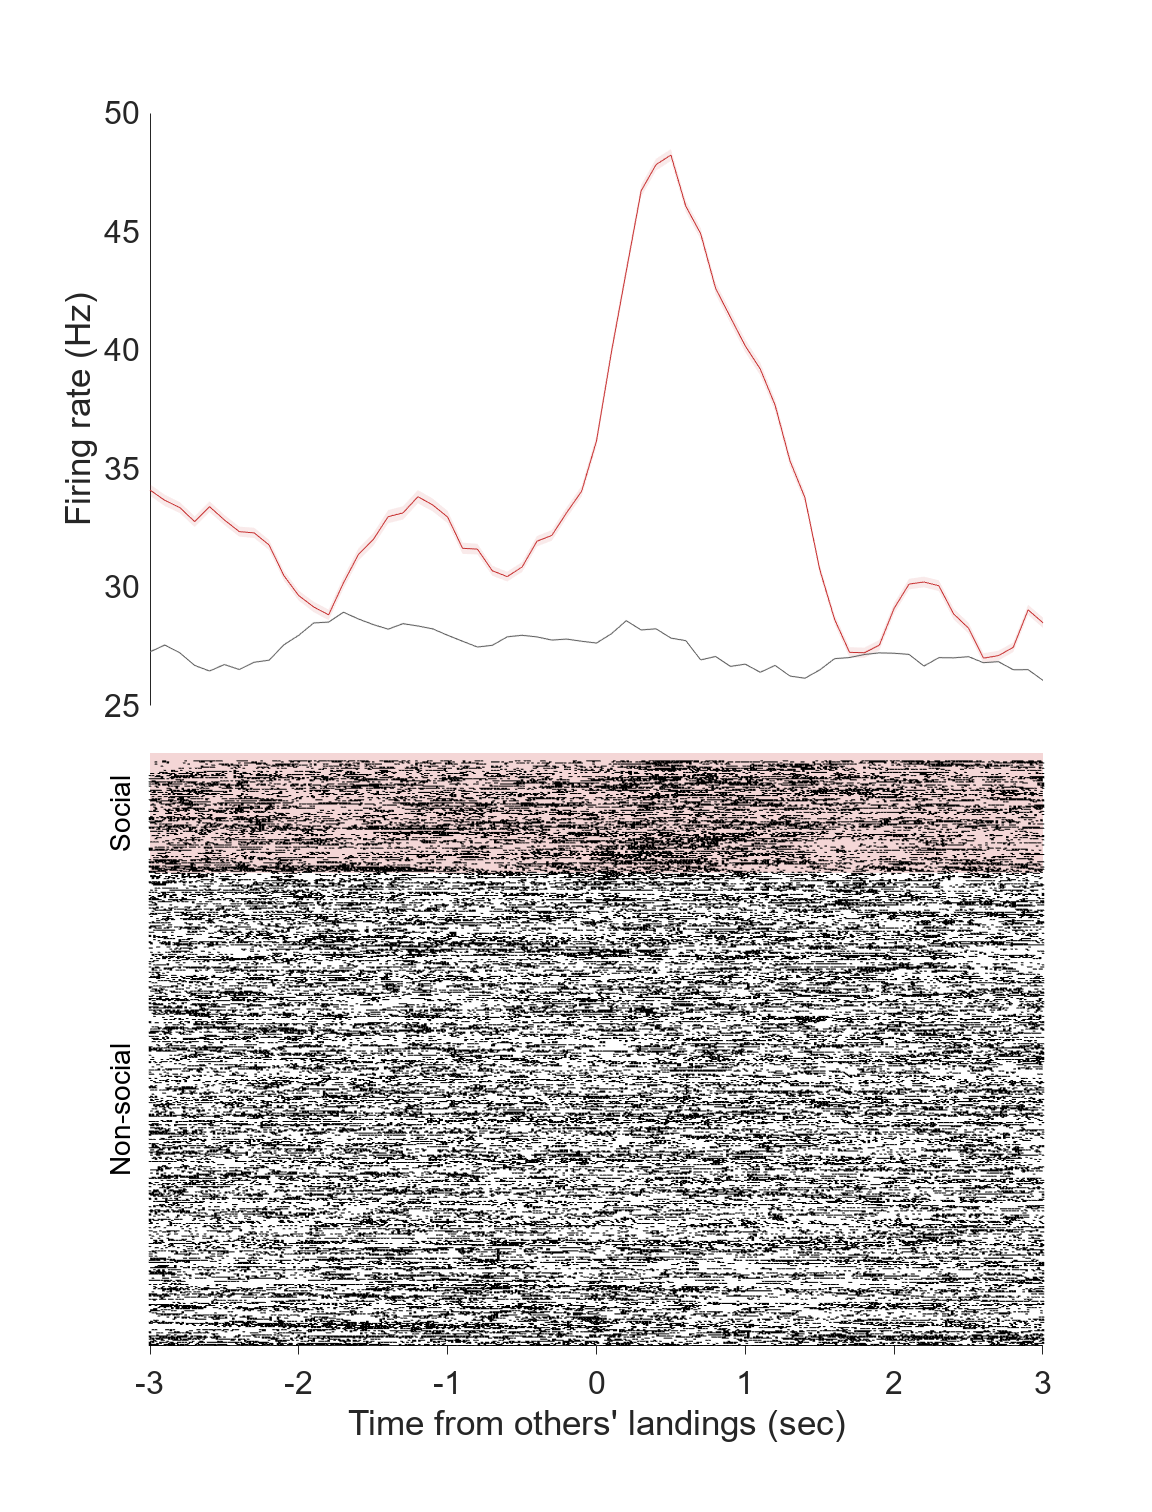

% Ephys bat ID
bb = find(strcmp(bname_ephys,mtData.bname));

% Parameters
t_margin = [-3 3]; % window range to evaluate social modualtion (sec)
th_social = 0.5; % threshold for social flight (m)
w_step = 0.1; % step size of window for optimizing time bin (sec)
w_sz = 0.5; % window size for optimizing time bin (sec)

% Load behavioral features
r = BhvData.r(:,:,bb); % position
v = BhvData.v_abs(:,bb); % velocity
t = BhvData.t; % time
n_bats = BhvData.n_tags; % # of bats
blanding = 1 - BhvData.bflying; % 1 if at resting sites
fs_bhv = BhvData.fs; % sampling frequency for behavioral data
n_flight = Flights(bb).n_flight; % # of flights
t_land_idx = Flights(bb).t_land_idx; % time index of landings
d_oth_rest = Flights(bb).dist_oth_rest;
t_lands = Flights(bb).t_land;
% is_social = Flights(bb).closest_oth_dist < th_social; % true if social flight


% Extract the timing of conspecifics landing
t_cland_sec = []; % conspecific land timings
is_social = [];
for bbb = [1:bb-1,bb+1:n_bats]
    for ll = 1:n_flight
        is_cland = diff([blanding(t_land_idx(ll,1),bbb); blanding(t_land_idx(ll,1):t_land_idx(ll,2),bbb)]) == 1;
        t_cland_sec = [t_cland_sec; t_lands{ll}(is_cland)];
        is_social = [is_social; d_oth_rest{ll}(is_cland,bbb) < th_social];
    end
end
is_social = logical(is_social);
[t_cland_sec,sort_idx] = sort(t_cland_sec);
is_social = is_social(sort_idx);

t_action_sec = t_cland_sec; % time of target events
n_event = length(t_cland_sec); % number of target events
n1 = sum(is_social); n2 = sum(~is_social);

% 1. Check exclusion criteria
if n_flight < 20 % minimum number of flights
    error('The number of flights is insufficient.')
end
if n1 < 10 || n2 < 10 % minimum number of flights per category
    error('The number of flights per category is insufficient.')
end
target_units =  spikeData.good_units.fr >= 0.2; % firing rate criteria

% Load neural features
unit_ids = spikeData.good_units.cluster_id(target_units);
sptimes_all_usec = spikeData.good_units.spikeTimes_usec(target_units);
unit_depths = spikeData.good_units.depth(target_units);
n_unit = sum(target_units);

% Exclude the behavioral data after the ephys recording stop
t_ephys_start = min(spikeData.allGlobalSpikeTimes_usec/1e6);
t_ephys_end = max(spikeData.allGlobalSpikeTimes_usec/1e6);
is_include = t_action_sec > t_ephys_start & t_action_sec < t_ephys_end;
t_action_sec = t_action_sec(is_include);
is_social = is_social(is_include);
n_event = length(t_action_sec);
n1 = sum(is_social);
n2 = sum(~is_social);

% recDay = 1;

%%%%% Run for all units
for unit = 12:12 % run for all units
% for unit = 20:20
    % Unit features
    unit_id = unit_ids(unit);
    depth = unit_depths(unit); % depth of unit
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = get_probe_region(layers,depth);
    sptimes_unit_sec = sptimes_all_usec{unit}/1e6; % spike times of the current unit in sec

    % 2. Determine the optimal time bin
    % Count spikes for each time bin
    sp_mat = zeros(n_event,diff(t_margin)/w_step+1+10); % spike count for each time bin (# of flights, # of time bins)
    sp_mat_2 = NaN(n_event,diff(t_margin)*fs_bhv+1);
    t_edges = [];
    for ff = 1:n_event
        t_edges(ff,:) = t_action_sec(ff)+t_margin(1)-w_step/2-5*w_step:w_step:t_action_sec(ff)+t_margin(2)+w_step/2+5*w_step;
        t_edges_2 = t_action_sec(ff)+t_margin(1)-1/fs_bhv/2:1/fs_bhv:t_action_sec(ff)+t_margin(2)+1/fs_bhv/2;
        sp_mat(ff,:) = histcounts(sptimes_unit_sec,t_edges(ff,:));
        sp_mat_2(ff,:) = histcounts(sptimes_unit_sec,t_edges_2);
    end
    % Screening with 500-ms time window
    e_test_poisson = NaN(3,size(sp_mat,2)); % row 1 = # of spikes for social flights, row 2 = # of spikes for non-social flights, row 3 = p-values for e-test
    e_test_poisson(1,:) = movsum(sum(sp_mat(is_social,:),1),w_sz/w_step);
    e_test_poisson(2,:) = movsum(sum(sp_mat(~is_social,:),1),w_sz/w_step);
    % for i = 1:size(e_test_poisson,2)
    %     e_test_poisson(3,i) = pois_mean_diff_test(e_test_poisson(1,i),e_test_poisson(2,i),'n1',n1,'n2',n2);
    % end
    % e_test_poisson(3,:) = e_test_poisson(3,:) * size(e_test_poisson,2); % Bon-Ferroni correction
    % % optimal time bin
    % [~,opt_bin] = min(e_test_poisson(3,:));
    % % opt_bin = 13;
    % t_opt_bin = mean(t_edges(:,opt_bin:opt_bin+1),2);

    % 3. Response variable: # of spikes for optimal bin (500ms window)
    % sp_counts = sum(sp_mat(:,opt_bin-2:opt_bin+2),2);
    % sp_counts = movsum(sp_mat,w_sz/w_step,2); sp_counts = sp_counts(:,opt_bin);

    % 4. Extract explanatory variables
    % idx_opt_bin = ismember(round(t,2),round(t_opt_bin,2));
    % [~,idx_opt_bin] = ismember(round(t_opt_bin,2),round(t,2));
    % r_x = r(idx_opt_bin,1);
    % r_y = r(idx_opt_bin,2);
    % v_abs = v(idx_opt_bin);
    % is_fd = double(is_fd);

    % 5. Stepwise GLM
    % T_vars = table(r_x,r_y,v_abs,is_social,sp_counts);
    % % T_vars = table(is_social,v_abs,r_x,sp_counts);
    % % mdl = stepwiseglm(T_vars,'constant','Lower','linear','Distribution','poisson','Link','log')
    % mdl = stepwiseglm(T_vars,'constant','Distribution','poisson','Link','log');
    % coef_names = mdl.CoefficientNames(2:end);
    % coef_pvalues = mdl.Coefficients.pValue(2:end);
    % coef_sig = coef_names(coef_pvalues < 0.01); % significant coefficients
    % coef_sig = join(coef_sig,',');

    %%% FIGURE: Firing rate curve and raster plot
    %%% Initialize figure bundle
    % fig = figure('visible','off');
    fig = figure;
    set(fig,'units','normalize','Position',[0.2 0.2 0.3 0.7])
    tl = tiledlayout(2,1,'TileSpacing','tight');
    % title_str = sprintf('Unit%d, %s',unit_id,region);
    title_str = sprintf('Unit%d',unit_id);
    title(tl,title_str,'Interpreter','None','FontSize',16)

    % Plot 1: Firing rate curve
    nexttile
    t_fig = t_margin(1):w_step:t_margin(2); % time vector for figure
    fr1 = e_test_poisson(1,:)/w_sz/n1; % firing rates for social flights
    fr2 = e_test_poisson(2,:)/w_sz/n2; % firing rates for non-social flights
    sem1 = std(movsum(sp_mat(is_social,:),w_sz/w_step,2)/w_sz,0,1) / n1; % standard error of mean for sllinding window (social flights)
    sem2 = std(movsum(sp_mat(~is_social,:),w_sz/w_step,2)/w_sz,0,1) / n2; % standard error of mean for sliding window (non-social flights)

    
    hold on
    % plot(t_fig,e_test_poisson(1,:)/w_sz/n1,'r','DisplayName','Social')
    % plot(t_fig,e_test_poisson(2,:)/w_sz/n2,'k','DisplayName','Non-social')
    boundedline(t_fig,fr1(6:end-5),sem1(6:end-5),'color',[200 50 50]/255,'alpha','transparency', 0.1)
    boundedline(t_fig,fr2(6:end-5),sem2(6:end-5),'color',[100 100 100]/255,'alpha','transparency', 0.1)
    hold off
    ylabel('Firing rate (Hz)')
    % xlabel('Time from landings (sec)')
    % yticks([])
    
    xlim(t_margin)
    % title_str = sprintf('Conspecific landings: p=%.4f \nGLM:%s',min(e_test_poisson(3,:)),coef_sig{:});
    % title(title_str,'Interpreter','None')
    set(gca,'FontSize',16,'XColor','none','TickDir','none')
    % Plot 2: raster plot
    nexttile
    t_bins = t_margin(1):1/fs_bhv:t_margin(2);
    [~,sort_idx] = sort(is_social);
    sp_mat_2_sort = sp_mat_2(sort_idx,:);
    
    
    % n2_new = 450; n1_new = n1;
    % sp_mat_2_new = sp_mat_2_sort([1:n2_new,n2+1:n2+n1_new],:);

    % t_fig = []; y_loc = [];
    % for ff = 1:size(sp_mat_2_sort,1)
    %     x_loc = find(sp_mat_2_sort(ff,:));
    %     t_fig = [t_fig, t_bins(x_loc)];
    %     y_loc = [y_loc, repmat(ff,1,length(x_loc))];
    % end
    t_fig = []; y_loc = [];
    for ff = 1:size(sp_mat_2_sort,1)
        x_loc = find(sp_mat_2_sort(ff,:));
        t_fig = [t_fig, t_bins(x_loc)];
        y_loc = [y_loc, repmat(ff,1,length(x_loc))];
    end
    t_fig = repmat(t_fig,2,1); y_loc = [y_loc-1; y_loc];
    hold on
    line(t_fig,y_loc,'Color','k','LineWidth',1.3)
    yregion(n2,n1+n2,'FaceColor',[200 50 50]/255,'FaceAlpha',0.2)
    % yregion(0,n2,'FaceColor',[100 100 100]/255)
    hold off
    xlim(t_margin)
    ylim([0,n1+n2])
    xlabel('Time from others'' landings (sec)')
    set(gca,'YTick',[],'TickDir','out','YColor','none','FontSize',16)

    % the arrows
    xO = -0.2;  
    yO = 0.5;
    x_fd1 = -3.1;
    x_fd2 = -3.1;
    y_fd1 = round(n2+n1/2);
    y_fd2 = round(n2/2);
    % patch(...
    %     [x_fd1+xO x_fd2+xO; x_fd1+xO x_fd1+xO; x_fd1 x_fd2], ...
    %     [y_fd1-yO y_fd2-yO; y_fd1+yO y_fd2+yO; y_fd1 y_fd2], 'k', 'clipping', 'off')

    % Texts
    text(x_fd1-0.1, y_fd1, 'Social', 'fontsize', 14,'HorizontalAlignment','center','Rotation',90)
    text(x_fd2-0.1, y_fd2, 'Non-social', 'fontsize', 14,'HorizontalAlignment','center','Rotation',90)


    %%% Save figure
    saveDir = fullfile(rootdir,'analysis','figure','social_modulation_all', ...
        sprintf('ephys%s',bname_ephys),trjName,'others_landing');
    if isempty(dir(saveDir)); mkdir(saveDir); end
    saveas(fig,fullfile(saveDir,sprintf('Unit%d.jpg',unit_id)))
    close(fig)
end   

### FIGURE3-2: example of neruson responsive to others takeoffs

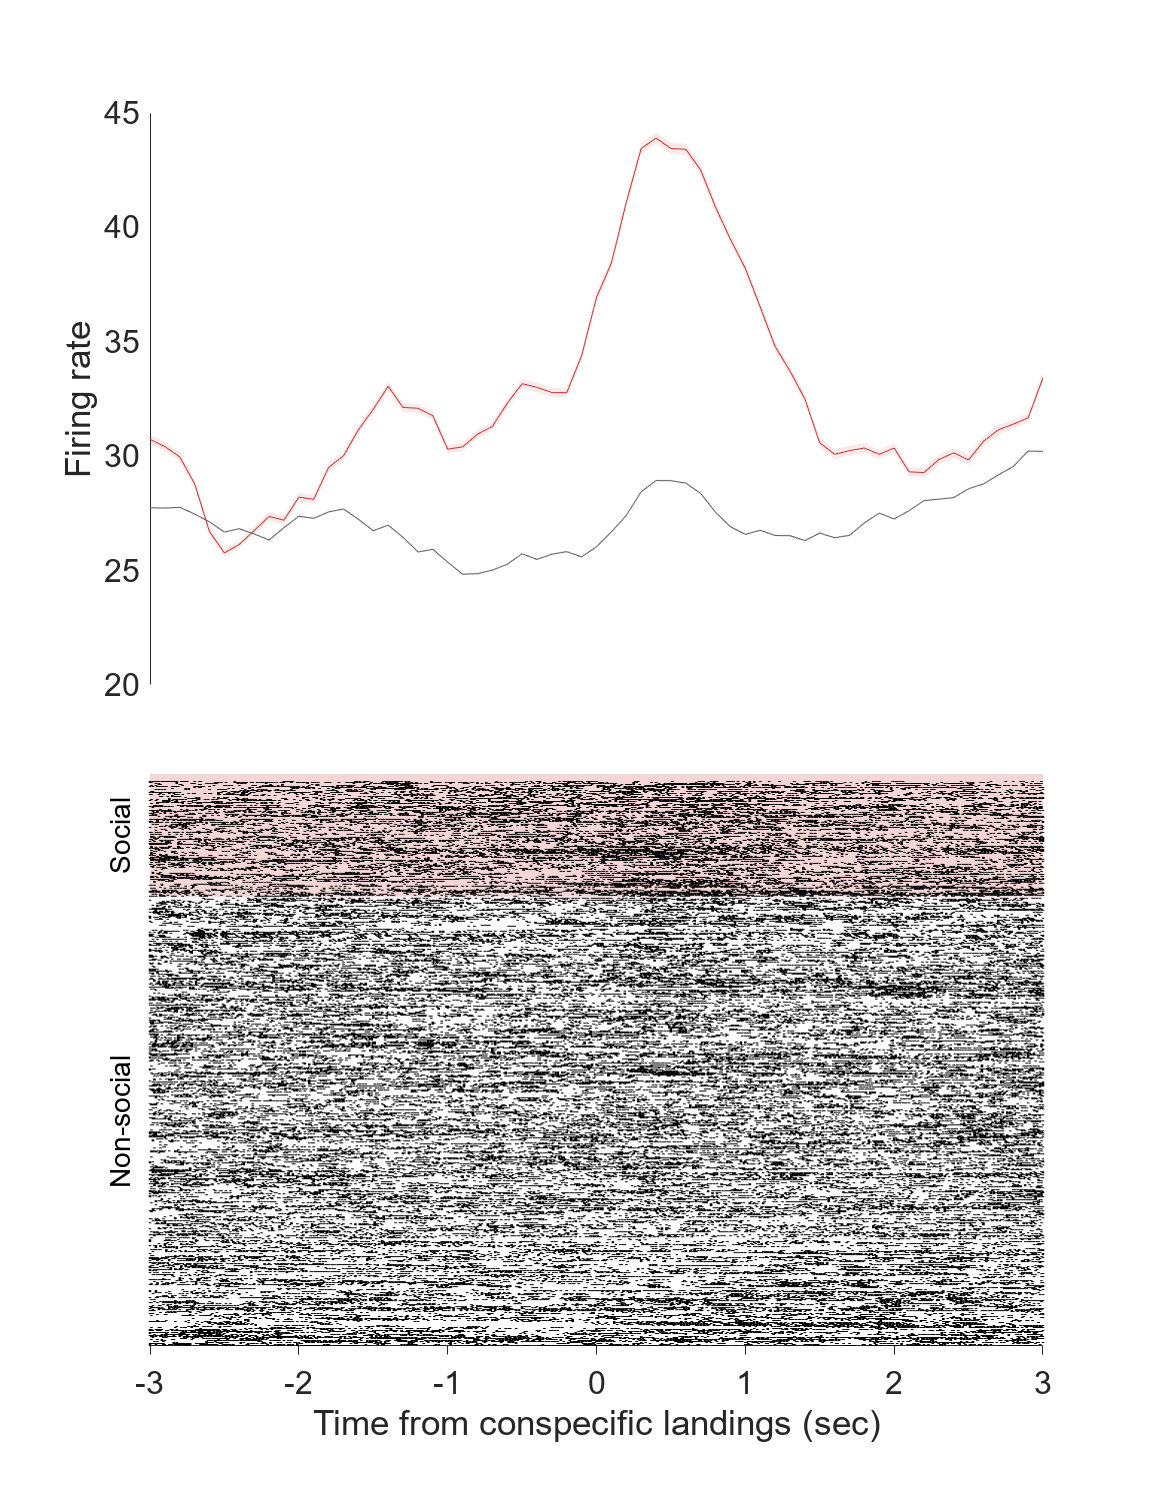

% Ephys bat ID
bb = find(strcmp(bname_ephys,mtData.bname));

% Parameters
t_margin = [-3 3]; % window range to evaluate social modualtion (sec)
th_social = 0.5; % threshold for social flight (m)
w_step = 0.1; % step size of window for optimizing time bin (sec)
w_sz = 0.5; % window size for optimizing time bin (sec)

% Load behavioral features
r = BhvData.r(:,:,bb); % position
v = BhvData.v_abs(:,bb); % velocity
t = BhvData.t; % time
n_bats = BhvData.n_tags; % # of bats
blanding = 1 - BhvData.bflying; % 1 if at resting sites
fs_bhv = BhvData.fs; % sampling frequency for behavioral data
n_flight = Flights(bb).n_flight; % # of flights
t_land_idx = Flights(bb).t_land_idx; % time index of landings
d_oth_rest = Flights(bb).dist_oth_rest;
t_lands = Flights(bb).t_land;
% is_social = Flights(bb).closest_oth_dist < th_social; % true if social flight


% Extract the timing of conspecifics landing
t_ctoff_sec = []; % conspecific land timings
is_social = [];
for bbb = [1:bb-1,bb+1:n_bats]
    for ll = 1:n_flight
        is_ctoff = diff([blanding(t_land_idx(ll,1),bbb); blanding(t_land_idx(ll,1):t_land_idx(ll,2),bbb)]) == -1;
        t_ctoff_sec = [t_ctoff_sec; t_lands{ll}(is_ctoff)];
        is_social = [is_social; d_oth_rest{ll}(is_ctoff,bbb) < th_social];
    end
end
is_social = logical(is_social);
[t_ctoff_sec,sort_idx] = sort(t_ctoff_sec);
is_social = is_social(sort_idx);

t_action_sec = t_ctoff_sec; % time of target events
n_event = length(t_ctoff_sec); % number of target events
n1 = sum(is_social); n2 = sum(~is_social);

% 1. Check exclusion criteria
if n_flight < 20 % minimum number of flights
    error('The number of flights is insufficient.')
end
if n1 < 10 || n2 < 10 % minimum number of flights per category
    error('The number of flights per category is insufficient.')
end
target_units =  spikeData.good_units.fr >= 0.2; % firing rate criteria

% Load neural features
unit_ids = spikeData.good_units.cluster_id(target_units);
sptimes_all_usec = spikeData.good_units.spikeTimes_usec(target_units);
unit_depths = spikeData.good_units.depth(target_units);
n_unit = sum(target_units);

% Exclude the behavioral data after the ephys recording stop
t_ephys_start = min(spikeData.allGlobalSpikeTimes_usec/1e6);
t_ephys_end = max(spikeData.allGlobalSpikeTimes_usec/1e6);
is_include = t_action_sec > t_ephys_start & t_action_sec < t_ephys_end;
t_action_sec = t_action_sec(is_include);
is_social = is_social(is_include);
n_event = length(t_action_sec);
n1 = sum(is_social);
n2 = sum(~is_social);


%%%%% Run for all units
for unit = 60:60 % run for all units
% for unit = 20:20
    % Unit features
    unit_id = unit_ids(unit);
    depth = unit_depths(unit); % depth of unit
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = get_probe_region(layers,depth);
    sptimes_unit_sec = sptimes_all_usec{unit}/1e6; % spike times of the current unit in sec

    % 2. Determine the optimal time bin
    % Count spikes for each time bin
    sp_mat = zeros(n_event,diff(t_margin)/w_step+1+10); % spike count for each time bin (# of flights, # of time bins)
    sp_mat_2 = NaN(n_event,diff(t_margin)*fs_bhv+1);
    t_edges = [];
    for ff = 1:n_event
        t_edges = t_action_sec(ff)+t_margin(1)-w_step/2-5*w_step:w_step:t_action_sec(ff)+t_margin(2)+w_step/2+5*w_step;
        t_edges_2 = t_action_sec(ff)+t_margin(1)-1/fs_bhv/2:1/fs_bhv:t_action_sec(ff)+t_margin(2)+1/fs_bhv/2;
        sp_mat(ff,:) = histcounts(sptimes_unit_sec,t_edges);
        sp_mat_2(ff,:) = histcounts(sptimes_unit_sec,t_edges_2);
    end
    % Screening with 500-ms time window
    e_test_poisson = NaN(3,size(sp_mat,2)); % row 1 = # of spikes for social flights, row 2 = # of spikes for non-social flights, row 3 = p-values for e-test
    e_test_poisson(1,:) = movsum(sum(sp_mat(is_social,:),1),w_sz/w_step);
    e_test_poisson(2,:) = movsum(sum(sp_mat(~is_social,:),1),w_sz/w_step);
    % for i = 1:size(e_test_poisson,2)
    %     e_test_poisson(3,i) = pois_mean_diff_test(e_test_poisson(1,i),e_test_poisson(2,i),'n1',n1,'n2',n2);
    % end
    % e_test_poisson(3,:) = e_test_poisson(3,:) * size(e_test_poisson,2); % Bon-Ferroni correction
    % % optimal time bin
    % [~,opt_bin] = min(e_test_poisson(3,:));
    % % opt_bin = 13;
    % t_opt_bin = mean(t_edges(:,opt_bin:opt_bin+1),2);

    % 3. Response variable: # of spikes for optimal bin (500ms window)
    % sp_counts = sum(sp_mat(:,opt_bin-2:opt_bin+2),2);
    % sp_counts = movsum(sp_mat,w_sz/w_step,2); sp_counts = sp_counts(:,opt_bin);

    % 4. Extract explanatory variables
    % idx_opt_bin = ismember(round(t,2),round(t_opt_bin,2));
    % [~,idx_opt_bin] = ismember(round(t_opt_bin,2),round(t,2));
    % r_x = r(idx_opt_bin,1);
    % r_y = r(idx_opt_bin,2);
    % v_abs = v(idx_opt_bin);
    % is_fd = double(is_fd);

    % 5. Stepwise GLM
    % T_vars = table(r_x,r_y,v_abs,is_social,sp_counts);
    % % T_vars = table(is_social,v_abs,r_x,sp_counts);
    % % mdl = stepwiseglm(T_vars,'constant','Lower','linear','Distribution','poisson','Link','log')
    % mdl = stepwiseglm(T_vars,'constant','Distribution','poisson','Link','log');
    % coef_names = mdl.CoefficientNames(2:end);
    % coef_pvalues = mdl.Coefficients.pValue(2:end);
    % coef_sig = coef_names(coef_pvalues < 0.01); % significant coefficients
    % coef_sig = join(coef_sig,',');

    %%% FIGURE: Firing rate curve and raster plot
    %%% Initialize figure bundle
    % fig = figure('visible','off');
    fig = figure;
    set(fig,'units','normalize','Position',[0.2 0.2 0.3 0.7])
    tl = tiledlayout(2,1,'TileSpacing','tight');
    title_str = sprintf('Unit%d',unit_id);
    title(tl,title_str,'Interpreter','None','FontSize',14)

    % Plot 1: Firing rate curve
    nexttile
    t_fig = t_margin(1):w_step:t_margin(2); % time vector for figure
    fr1 = e_test_poisson(1,:)/w_sz/n1; % firing rates for social flights
    fr2 = e_test_poisson(2,:)/w_sz/n2; % firing rates for non-social flights
    sem1 = std(movsum(sp_mat(is_social,:),w_sz/w_step,2)/w_sz,0,1) / n1; % standard error of mean for sllinding window (social flights)
    sem2 = std(movsum(sp_mat(~is_social,:),w_sz/w_step,2)/w_sz,0,1) / n2; % standard error of mean for sliding window (non-social flights)

    
    hold on
    % plot(t_fig,e_test_poisson(1,:)/w_sz/n1,'r','DisplayName','Social')
    % plot(t_fig,e_test_poisson(2,:)/w_sz/n2,'k','DisplayName','Non-social')
    boundedline(t_fig,fr1(6:end-5),sem1(6:end-5),'color',[200 50 50]/255,'alpha','transparency', 0.1)
    boundedline(t_fig,fr2(6:end-5),sem2(6:end-5),'color',[100 100 100]/255,'alpha','transparency', 0.1)
    hold off
    ylabel('Firing rate')
    xlabel('Time from others'' takeoffs (sec)')
    % yticks([])
    
    xlim(t_margin)
    % title_str = sprintf('Conspecific landings: p=%.4f \nGLM:%s',min(e_test_poisson(3,:)),coef_sig{:});
    % title(title_str,'Interpreter','None')
    set(gca,'FontSize',16,'XColor','none','TickDir','none')
    % Plot 2: raster plot
    nexttile
    t_bins = t_margin(1):1/fs_bhv:t_margin(2);
    [~,sort_idx] = sort(is_social);
    sp_mat_2_sort = sp_mat_2(sort_idx,:);
    
   
    % t_fig = []; y_loc = [];
    % for ff = 1:size(sp_mat_2_sort,1)
    %     x_loc = find(sp_mat_2_sort(ff,:));
    %     t_fig = [t_fig, t_bins(x_loc)];
    %     y_loc = [y_loc, repmat(ff,1,length(x_loc))];
    % end
    t_fig = []; y_loc = [];
    for ff = 1:size(sp_mat_2_sort,1)
        x_loc = find(sp_mat_2_sort(ff,:));
        t_fig = [t_fig, t_bins(x_loc)];
        y_loc = [y_loc, repmat(ff,1,length(x_loc))];
    end
    t_fig = repmat(t_fig,2,1); y_loc = [y_loc-1; y_loc];
    hold on
    line(t_fig,y_loc,'Color','k','LineWidth',1.3)
    yregion(n2,n1+n2,'FaceColor',[200 50 50]/255,'FaceAlpha',0.2)
    % yregion(0,n2,'FaceColor',[100 100 100]/255)
    hold off
    xlim(t_margin)
    ylim([0,n1+n2])
    xlabel('Time from others'' takeoffs (sec)')
    set(gca,'YTick',[],'TickDir','out','YColor','none','FontSize',16)

    % the arrows
    xO = -0.2;  
    yO = 0.5;
    x_fd1 = -3.1;
    x_fd2 = -3.1;
    y_fd1 = round(n2+n1/2);
    y_fd2 = round(n2/2);
    % patch(...
    %     [x_fd1+xO x_fd2+xO; x_fd1+xO x_fd1+xO; x_fd1 x_fd2], ...
    %     [y_fd1-yO y_fd2-yO; y_fd1+yO y_fd2+yO; y_fd1 y_fd2], 'k', 'clipping', 'off')

    % Texts
    text(x_fd1-0.1, y_fd1, 'Social', 'fontsize', 14,'HorizontalAlignment','center','Rotation',90)
    text(x_fd2-0.1, y_fd2, 'Non-social', 'fontsize', 14,'HorizontalAlignment','center','Rotation',90)


    %%% Save figure
    saveDir = fullfile(rootdir,'analysis','figure','social_modulation_all', ...
        sprintf('ephys%s',bname_ephys),trjName,'others_takeoff');
    if isempty(dir(saveDir)); mkdir(saveDir); end
    saveas(fig,fullfile(saveDir,sprintf('Unit%d.jpg',unit_id)))
    close(fig)
end   

### All others landings

% Ephys bat ID
bb = find(strcmp(bname_ephys,mtData.bname));

% Parameters
t_margin = [-3 3]; % window range to evaluate social modualtion (sec)
th_social = 0.5; % threshold for social flight (m)
w_step = 0.1; % step size of window for optimizing time bin (sec)
w_sz = 0.5; % window size for optimizing time bin (sec)

% Load behavioral features
r = BhvData.r(:,:,bb); % position
v = BhvData.v_abs(:,bb); % velocity
t = BhvData.t; % time
n_bats = BhvData.n_tags; % # of bats
blanding = 1 - BhvData.bflying; % 1 if at resting sites
fs_bhv = BhvData.fs; % sampling frequency for behavioral data
n_flight = Flights(bb).n_flight; % # of flights
t_land_idx = Flights(bb).t_land_idx; % time index of landings
d_oth_rest = Flights(bb).dist_oth_rest;
t_lands = Flights(bb).t_land;
% is_social = Flights(bb).closest_oth_dist < th_social; % true if social flight


% Extract the timing of conspecifics landing
t_ctoff_sec = []; % conspecific land timings
is_social = [];
for bbb = [1:bb-1,bb+1:n_bats]
    for ll = 1:n_flight
        is_ctoff = diff([blanding(t_land_idx(ll,1),bbb); blanding(t_land_idx(ll,1):t_land_idx(ll,2),bbb)]) == 1;
        t_ctoff_sec = [t_ctoff_sec; t_lands{ll}(is_ctoff)];
        is_social = [is_social; d_oth_rest{ll}(is_ctoff,bbb) < th_social];
    end
end
is_social = logical(is_social);
[t_ctoff_sec,sort_idx] = sort(t_ctoff_sec);
is_social = is_social(sort_idx);

t_action_sec = t_ctoff_sec; % time of target events
n_event = length(t_ctoff_sec); % number of target events
n1 = sum(is_social); n2 = sum(~is_social);

% 1. Check exclusion criteria
if n_flight < 20 % minimum number of flights
    error('The number of flights is insufficient.')
end
if n1 < 10 || n2 < 10 % minimum number of flights per category
    error('The number of flights per category is insufficient.')
end
target_units =  spikeData.good_units.fr >= 0.2 & strcmp(spikeData.good_units.region,'MEC'); % firing rate criteria

% Load neural features
unit_ids = spikeData.good_units.cluster_id(target_units);
sptimes_all_usec = spikeData.good_units.spikeTimes_usec(target_units);
unit_depths = spikeData.good_units.depth(target_units);
n_unit = sum(target_units);

% Exclude the behavioral data after the ephys recording stop
t_ephys_start = min(spikeData.allGlobalSpikeTimes_usec/1e6);
t_ephys_end = max(spikeData.allGlobalSpikeTimes_usec/1e6);
is_include = t_action_sec > t_ephys_start & t_action_sec < t_ephys_end;
t_action_sec = t_action_sec(is_include);
is_social = is_social(is_include);
n_event = length(t_action_sec);
n1 = sum(is_social);
n2 = sum(~is_social);

%%%%% Run for all units
for unit = 1:n_unit % run for all units
    disp(sprintf('Running %d/%d...',unit,n_unit))
% for unit = 1:1
    % Unit features
    unit_id = unit_ids(unit);
    depth = unit_depths(unit); % depth of unit
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = get_probe_region(layers,depth);
    sptimes_unit_sec = sptimes_all_usec{unit}/1e6; % spike times of the current unit in sec

    % 2. Determine the optimal time bin
    % Count spikes for each time bin
    sp_mat = zeros(n_event,diff(t_margin)/w_step+1+10); % spike count for each time bin (# of flights, # of time bins)
    sp_mat_2 = NaN(n_event,diff(t_margin)*fs_bhv+1);
    % t_edges= [];
    for ff = 1:n_event
        t_edges = t_action_sec(ff)+t_margin(1)-w_step/2-5*w_step:w_step:t_action_sec(ff)+t_margin(2)+w_step/2+5*w_step;
        t_edges_2 = t_action_sec(ff)+t_margin(1)-1/fs_bhv/2:1/fs_bhv:t_action_sec(ff)+t_margin(2)+1/fs_bhv/2;
        sp_mat(ff,:) = histcounts(sptimes_unit_sec,t_edges);
        sp_mat_2(ff,:) = histcounts(sptimes_unit_sec,t_edges_2);
    end
    % Screening with 500-ms time window
    e_test_poisson = NaN(3,size(sp_mat,2)); % row 1 = # of spikes for social flights, row 2 = # of spikes for non-social flights, row 3 = p-values for e-test
    e_test_poisson(1,:) = movsum(sum(sp_mat(is_social,:),1),w_sz/w_step);
    e_test_poisson(2,:) = movsum(sum(sp_mat(~is_social,:),1),w_sz/w_step);
    % for i = 1:size(e_test_poisson,2)
    %     e_test_poisson(3,i) = pois_mean_diff_test(e_test_poisson(1,i),e_test_poisson(2,i),'n1',n1,'n2',n2);
    % end
    % e_test_poisson(3,:) = e_test_poisson(3,:) * size(e_test_poisson,2); % Bon-Ferroni correction
    % % optimal time bin
    % [~,opt_bin] = min(e_test_poisson(3,:));
    % % opt_bin = 13;
    % t_opt_bin = mean(t_edges(:,opt_bin:opt_bin+1),2);

    % 3. Response variable: # of spikes for optimal bin (500ms window)
    % sp_counts = sum(sp_mat(:,opt_bin-2:opt_bin+2),2);
    % sp_counts = movsum(sp_mat,w_sz/w_step,2); sp_counts = sp_counts(:,opt_bin);

    % 4. Extract explanatory variables
    % idx_opt_bin = ismember(round(t,2),round(t_opt_bin,2));
    % [~,idx_opt_bin] = ismember(round(t_opt_bin,2),round(t,2));
    % r_x = r(idx_opt_bin,1);
    % r_y = r(idx_opt_bin,2);
    % v_abs = v(idx_opt_bin);
    % is_fd = double(is_fd);

    % 5. Stepwise GLM
    % T_vars = table(r_x,r_y,v_abs,is_social,sp_counts);
    % % T_vars = table(is_social,v_abs,r_x,sp_counts);
    % % mdl = stepwiseglm(T_vars,'constant','Lower','linear','Distribution','poisson','Link','log')
    % mdl = stepwiseglm(T_vars,'constant','Distribution','poisson','Link','log');
    % coef_names = mdl.CoefficientNames(2:end);
    % coef_pvalues = mdl.Coefficients.pValue(2:end);
    % coef_sig = coef_names(coef_pvalues < 0.01); % significant coefficients
    % coef_sig = join(coef_sig,',');

    %%% FIGURE: Firing rate curve and raster plot
    %%% Initialize figure bundle
    % fig = figure('visible','off');
    fig = figure;
    set(fig,'units','normalize','Position',[0.2 0.2 0.3 0.7])
    tl = tiledlayout(2,1,'TileSpacing','tight');
    % title_str = sprintf('Unit%d, %s',unit_id,region);
    % title(tl,title_str,'Interpreter','None','FontSize',14)

    % Plot 1: Firing rate curve
    nexttile
    t_fig = t_margin(1):w_step:t_margin(2); % time vector for figure
    fr1 = e_test_poisson(1,:)/w_sz/n1; % firing rates for social flights
    fr2 = e_test_poisson(2,:)/w_sz/n2; % firing rates for non-social flights
    sem1 = std(movsum(sp_mat(is_social,:),w_sz/w_step,2)/w_sz,0,1) / n1; % standard error of mean for sllinding window (social flights)
    sem2 = std(movsum(sp_mat(~is_social,:),w_sz/w_step,2)/w_sz,0,1) / n2; % standard error of mean for sliding window (non-social flights)
    % 
    % % normalize firing rate
    % sem1 = ((sem1 * n1 - mean(fr1)) / std(fr1)) / n1;
    % sem2 = ((sem2 * n2 - mean(fr2)) / std(fr2)) / n2;
    % 
    % fr1 = (fr1 - mean(fr1)) / std(fr1);
    % fr2 = (fr2 - mean(fr2)) / std(fr2);
    % 
    % 
    hold on
    % plot(t_fig,e_test_poisson(1,:)/w_sz/n1,'r','DisplayName','Social')
    % plot(t_fig,e_test_poisson(2,:)/w_sz/n2,'k','DisplayName','Non-social')
    boundedline(t_fig,fr1(6:end-5),sem1(6:end-5),'color',[200 50 50]/255,'alpha','transparency', 0.1)
    boundedline(t_fig,fr2(6:end-5),sem2(6:end-5),'color',[100 100 100]/255,'alpha','transparency', 0.1)
    hold off
    ylabel('Firing rate')
    % xlabel('Time from landings (sec)')
    % yticks([])
    
    xlim(t_margin)
    % title_str = sprintf('Conspecific landings: p=%.4f \nGLM:%s',min(e_test_poisson(3,:)),coef_sig{:});
    % title(title_str,'Interpreter','None')
    set(gca,'FontSize',16,'XColor','none','TickDir','none')

    % Plot 2: raster plot
    nexttile
    t_bins = t_margin(1):1/fs_bhv:t_margin(2);
    [~,sort_idx] = sort(is_social);
    sp_mat_2_sort = sp_mat_2(sort_idx,:);
    
    
    n2_new = n2; n1_new = n1;
    sp_mat_2_new = sp_mat_2_sort([1:n2_new,n2+1:n2+n1_new],:);

    % t_fig = []; y_loc = [];
    % for ff = 1:size(sp_mat_2_sort,1)
    %     x_loc = find(sp_mat_2_sort(ff,:));
    %     t_fig = [t_fig, t_bins(x_loc)];
    %     y_loc = [y_loc, repmat(ff,1,length(x_loc))];
    % end
    t_fig = []; y_loc = [];
    for ff = 1:size(sp_mat_2_new,1)
        x_loc = find(sp_mat_2_new(ff,:));
        t_fig = [t_fig, t_bins(x_loc)];
        y_loc = [y_loc, repmat(ff,1,length(x_loc))];
    end
    t_fig = repmat(t_fig,2,1); y_loc = [y_loc-1; y_loc];
    hold on
    line(t_fig,y_loc,'Color','k','LineWidth',1.3)
    yregion(n2_new,n1_new+n2_new,'FaceColor',[200 50 50]/255,'FaceAlpha',0.2)
    % yregion(0,n2,'FaceColor',[100 100 100]/255)
    hold off
    xlim(t_margin)
    ylim([0,n1_new+n2_new])
    xlabel('Time from conspecific landings (sec)')
    set(gca,'YTick',[],'TickDir','out','YColor','none','FontSize',16)

    % the arrows
    xO = -0.2;  
    yO = 0.5;
    x_fd1 = -3.1;
    x_fd2 = -3.1;
    y_fd1 = round(n2_new+n1_new/2);
    y_fd2 = round(n2_new/2);
    % patch(...
    %     [x_fd1+xO x_fd2+xO; x_fd1+xO x_fd1+xO; x_fd1 x_fd2], ...
    %     [y_fd1-yO y_fd2-yO; y_fd1+yO y_fd2+yO; y_fd1 y_fd2], 'k', 'clipping', 'off')

    % Texts
    text(x_fd1-0.1, y_fd1, 'Social', 'fontsize', 14,'HorizontalAlignment','center','Rotation',90)
    text(x_fd2-0.1, y_fd2, 'Non-social', 'fontsize', 14,'HorizontalAlignment','center','Rotation',90)


    %%% Save figure
    saveDir = fullfile(rootdir,'analysis','figure','social_modulation_all', ...
        sprintf('ephys%s',bname_ephys),trjName,'others_landing');
    if isempty(dir(saveDir)); mkdir(saveDir); end
    saveas(fig,fullfile(saveDir,sprintf('Unit%d.jpg',unit_id)))
    close(fig)
end   

Running 1/22...
Running 2/22...
Running 3/22...
Running 4/22...
Running 5/22...
Running 6/22...
Running 7/22...
Running 8/22...
Running 9/22...
Running 10/22...
Running 11/22...
Running 12/22...
Running 13/22...
Running 14/22...
Running 15/22...
Running 16/22...
Running 17/22...
Running 18/22...
Running 19/22...
Running 20/22...
Running 21/22...
Running 22/22...


### All others takeoffs

    % Ephys bat ID
bb = find(strcmp(bname_ephys,mtData.bname));

% Parameters
t_margin = [-3 3]; % window range to evaluate social modualtion (sec)
th_social = 0.5; % threshold for social flight (m)
w_step = 0.1; % step size of window for optimizing time bin (sec)
w_sz = 0.5; % window size for optimizing time bin (sec)

% Load behavioral features
r = BhvData.r(:,:,bb); % position
v = BhvData.v_abs(:,bb); % velocity
t = BhvData.t; % time
n_bats = BhvData.n_tags; % # of bats
blanding = 1 - BhvData.bflying; % 1 if at resting sites
fs_bhv = BhvData.fs; % sampling frequency for behavioral data
n_flight = Flights(bb).n_flight; % # of flights
t_land_idx = Flights(bb).t_land_idx; % time index of landings
d_oth_rest = Flights(bb).dist_oth_rest;
t_lands = Flights(bb).t_land;
% is_social = Flights(bb).closest_oth_dist < th_social; % true if social flight


% Extract the timing of conspecifics landing
t_ctoff_sec = []; % conspecific land timings
is_social = [];
for bbb = [1:bb-1,bb+1:n_bats]
    for ll = 1:n_flight
        is_ctoff = diff([blanding(t_land_idx(ll,1),bbb); blanding(t_land_idx(ll,1):t_land_idx(ll,2),bbb)]) == -1;
        t_ctoff_sec = [t_ctoff_sec; t_lands{ll}(is_ctoff)];
        is_social = [is_social; d_oth_rest{ll}(is_ctoff,bbb) < th_social];
    end
end
is_social = logical(is_social);
[t_ctoff_sec,sort_idx] = sort(t_ctoff_sec);
is_social = is_social(sort_idx);

t_action_sec = t_ctoff_sec; % time of target events
n_event = length(t_ctoff_sec); % number of target events
n1 = sum(is_social); n2 = sum(~is_social);

% 1. Check exclusion criteria
if n_flight < 20 % minimum number of flights
    error('The number of flights is insufficient.')
end
if n1 < 10 || n2 < 10 % minimum number of flights per category
    error('The number of flights per category is insufficient.')
end
target_units =  spikeData.good_units.fr >= 0.2 & strcmp(spikeData.good_units.region,'MEC'); % firing rate criteria

% Load neural features
unit_ids = spikeData.good_units.cluster_id(target_units);
sptimes_all_usec = spikeData.good_units.spikeTimes_usec(target_units);
unit_depths = spikeData.good_units.depth(target_units);
n_unit = sum(target_units);

% Exclude the behavioral data after the ephys recording stop
t_ephys_start = min(spikeData.allGlobalSpikeTimes_usec/1e6);
t_ephys_end = max(spikeData.allGlobalSpikeTimes_usec/1e6);
is_include = t_action_sec > t_ephys_start & t_action_sec < t_ephys_end;
t_action_sec = t_action_sec(is_include);
is_social = is_social(is_include);
n_event = length(t_action_sec);
n1 = sum(is_social);
n2 = sum(~is_social);

%%%%% Run for all units
for unit = 1:n_unit % run for all units
    disp(sprintf('Running %d/%d...',unit,n_unit))
% for unit = 20:20
    % Unit features
    unit_id = unit_ids(unit);
    depth = unit_depths(unit); % depth of unit
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = get_probe_region(layers,depth);
    sptimes_unit_sec = sptimes_all_usec{unit}/1e6; % spike times of the current unit in sec

    % 2. Determine the optimal time bin
    % Count spikes for each time bin
    sp_mat = zeros(n_event,diff(t_margin)/w_step+1+10); % spike count for each time bin (# of flights, # of time bins)
    sp_mat_2 = NaN(n_event,diff(t_margin)*fs_bhv+1);
    t_edges = [];
    for ff = 1:n_event
        t_edges(ff,:) = t_action_sec(ff)+t_margin(1)-w_step/2-5*w_step:w_step:t_action_sec(ff)+t_margin(2)+w_step/2+5*w_step;
        t_edges_2 = t_action_sec(ff)+t_margin(1)-1/fs_bhv/2:1/fs_bhv:t_action_sec(ff)+t_margin(2)+1/fs_bhv/2;
        sp_mat(ff,:) = histcounts(sptimes_unit_sec,t_edges(ff,:));
        sp_mat_2(ff,:) = histcounts(sptimes_unit_sec,t_edges_2);
    end
    % Screening with 500-ms time window
    e_test_poisson = NaN(3,size(sp_mat,2)); % row 1 = # of spikes for social flights, row 2 = # of spikes for non-social flights, row 3 = p-values for e-test
    e_test_poisson(1,:) = movsum(sum(sp_mat(is_social,:),1),w_sz/w_step);
    e_test_poisson(2,:) = movsum(sum(sp_mat(~is_social,:),1),w_sz/w_step);
    % for i = 1:size(e_test_poisson,2)
    %     e_test_poisson(3,i) = pois_mean_diff_test(e_test_poisson(1,i),e_test_poisson(2,i),'n1',n1,'n2',n2);
    % end
    % e_test_poisson(3,:) = e_test_poisson(3,:) * size(e_test_poisson,2); % Bon-Ferroni correction
    % % optimal time bin
    % [~,opt_bin] = min(e_test_poisson(3,:));
    % % opt_bin = 13;
    % t_opt_bin = mean(t_edges(:,opt_bin:opt_bin+1),2);

    % 3. Response variable: # of spikes for optimal bin (500ms window)
    % sp_counts = sum(sp_mat(:,opt_bin-2:opt_bin+2),2);
    % sp_counts = movsum(sp_mat,w_sz/w_step,2); sp_counts = sp_counts(:,opt_bin);

    % 4. Extract explanatory variables
    % idx_opt_bin = ismember(round(t,2),round(t_opt_bin,2));
    % [~,idx_opt_bin] = ismember(round(t_opt_bin,2),round(t,2));
    % r_x = r(idx_opt_bin,1);
    % r_y = r(idx_opt_bin,2);
    % v_abs = v(idx_opt_bin);
    % is_fd = double(is_fd);

    % 5. Stepwise GLM
    % T_vars = table(r_x,r_y,v_abs,is_social,sp_counts);
    % % T_vars = table(is_social,v_abs,r_x,sp_counts);
    % % mdl = stepwiseglm(T_vars,'constant','Lower','linear','Distribution','poisson','Link','log')
    % mdl = stepwiseglm(T_vars,'constant','Distribution','poisson','Link','log');
    % coef_names = mdl.CoefficientNames(2:end);
    % coef_pvalues = mdl.Coefficients.pValue(2:end);
    % coef_sig = coef_names(coef_pvalues < 0.01); % significant coefficients
    % coef_sig = join(coef_sig,',');

    %%% FIGURE: Firing rate curve and raster plot
    %%% Initialize figure bundle
    fig = figure('visible','off');
    % fig = figure;
    set(fig,'units','normalize','Position',[0.2 0.2 0.3 0.7])
    tl = tiledlayout(2,1,'TileSpacing','tight');
    % title_str = sprintf('Unit%d, %s',unit_id,region);
    % title(tl,title_str,'Interpreter','None','FontSize',14)

    % Plot 1: Firing rate curve
    nexttile
    t_fig = t_margin(1):w_step:t_margin(2); % time vector for figure
    fr1 = e_test_poisson(1,:)/w_sz/n1; % firing rates for social flights
    fr2 = e_test_poisson(2,:)/w_sz/n2; % firing rates for non-social flights
    sem1 = std(movsum(sp_mat(is_social,:),w_sz/w_step,2)/w_sz,0,1) / n1; % standard error of mean for sllinding window (social flights)
    sem2 = std(movsum(sp_mat(~is_social,:),w_sz/w_step,2)/w_sz,0,1) / n2; % standard error of mean for sliding window (non-social flights)

    
    hold on
    % plot(t_fig,e_test_poisson(1,:)/w_sz/n1,'r','DisplayName','Social')
    % plot(t_fig,e_test_poisson(2,:)/w_sz/n2,'k','DisplayName','Non-social')
    boundedline(t_fig,fr1(6:end-5),sem1(6:end-5),'color',[200 50 50]/255,'alpha','transparency', 0.1)
    boundedline(t_fig,fr2(6:end-5),sem2(6:end-5),'color',[100 100 100]/255,'alpha','transparency', 0.1)
    hold off
    ylabel('Firing rate')
    % xlabel('Time from conspecific takeoffs (sec)')
    % yticks([])
    
    xlim(t_margin)
    % title_str = sprintf('Conspecific landings: p=%.4f \nGLM:%s',min(e_test_poisson(3,:)),coef_sig{:});
    % title(title_str,'Interpreter','None')
    set(gca,'FontSize',16,'XColor','none','TickDir','none')
    % Plot 2: raster plot
    nexttile
    t_bins = t_margin(1):1/fs_bhv:t_margin(2);
    [~,sort_idx] = sort(is_social);
    sp_mat_2_sort = sp_mat_2(sort_idx,:);
    
    
    n2_new = n2; n1_new = n1;
    sp_mat_2_new = sp_mat_2_sort([1:n2_new,n2+1:n2+n1_new],:);

    % t_fig = []; y_loc = [];
    % for ff = 1:size(sp_mat_2_sort,1)
    %     x_loc = find(sp_mat_2_sort(ff,:));
    %     t_fig = [t_fig, t_bins(x_loc)];
    %     y_loc = [y_loc, repmat(ff,1,length(x_loc))];
    % end
    t_fig = []; y_loc = [];
    for ff = 1:size(sp_mat_2_new,1)
        x_loc = find(sp_mat_2_new(ff,:));
        t_fig = [t_fig, t_bins(x_loc)];
        y_loc = [y_loc, repmat(ff,1,length(x_loc))];
    end
    t_fig = repmat(t_fig,2,1); y_loc = [y_loc-1; y_loc];
    hold on
    line(t_fig,y_loc,'Color','k','LineWidth',1.3)
    yregion(n2_new,n1_new+n2_new,'FaceColor',[200 50 50]/255,'FaceAlpha',0.2)
    % yregion(0,n2,'FaceColor',[100 100 100]/255)
    hold off
    xlim(t_margin)
    ylim([0,n1_new+n2_new])
    xlabel('Time from conspecific takeoffs (sec)')
    set(gca,'YTick',[],'TickDir','out','YColor','none','FontSize',16)

    % the arrows
    xO = -0.2;  
    yO = 0.5;
    x_fd1 = -3.1;
    x_fd2 = -3.1;
    y_fd1 = round(n2_new+n1_new/2);
    y_fd2 = round(n2_new/2);
    % patch(...
    %     [x_fd1+xO x_fd2+xO; x_fd1+xO x_fd1+xO; x_fd1 x_fd2], ...
    %     [y_fd1-yO y_fd2-yO; y_fd1+yO y_fd2+yO; y_fd1 y_fd2], 'k', 'clipping', 'off')

    % Texts
    text(x_fd1-0.1, y_fd1, 'Social', 'fontsize', 14,'HorizontalAlignment','center','Rotation',90)
    text(x_fd2-0.1, y_fd2, 'Non-social', 'fontsize', 14,'HorizontalAlignment','center','Rotation',90)


    %%% Save figure
    saveDir = fullfile(rootdir,'analysis','figure','social_modulation_all', ...
        sprintf('ephys%s',bname_ephys),trjName,'others_takeoff');
    if isempty(dir(saveDir)); mkdir(saveDir); end
    saveas(fig,fullfile(saveDir,sprintf('Unit%d.jpg',unit_id)))
    close(fig)
end   

Running 1/22...
Running 2/22...
Running 3/22...
Running 4/22...
Running 5/22...
Running 6/22...
Running 7/22...
Running 8/22...
Running 9/22...
Running 10/22...
Running 11/22...
Running 12/22...
Running 13/22...
Running 14/22...
Running 15/22...
Running 16/22...
Running 17/22...
Running 18/22...
Running 19/22...
Running 20/22...
Running 21/22...
Running 22/22...


####  Number of socially modulated neurons

A_land = [10/31, 12/41, 7/42];
A_toff = [13/31, 7/41, 3/42];

mean(A_land)

ans = 0.2606

std(A_land)

ans = 0.0827

mean(A_toff)

ans = 0.2205

std(A_toff)

ans = 0.1792